clear;clc;clf;

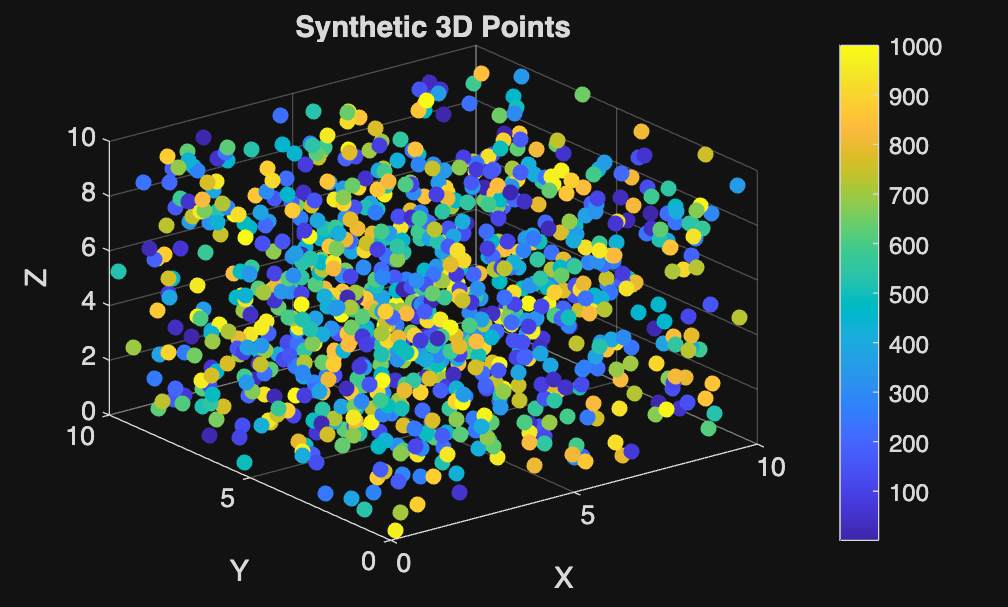

%% Step 1: Generate Synthetic 3D Points in a Rotated Circle Above Z=0
function points3D = generate3DPoints(numPoints, seed, rotationAngle, shape)
    rng(seed);
    if strcmp(shape, 'circle')
        theta = linspace(0, 2*pi, numPoints)'; % Angle for circular arrangement
        radius = 4; % Circle radius
        x = radius * cos(theta); % X coordinates
        y = zeros(numPoints, 1); % Keep all points on the x-z plane
        z = radius * sin(theta) + 4; % Shift Z coordinates above 0
        
        % Rotation matrix for rotation about the X-axis
        R = [1, 0, 0;
             0, cos(rotationAngle), -sin(rotationAngle);
             0, sin(rotationAngle), cos(rotationAngle)];
        
        rotatedPoints = (R * [x, y, z]')'; % Apply rotation
    elseif strcmp(shape, 'cube')
        rotatedPoints = 10 * rand(numPoints, 3); % Generate points in [0,10]^3
    else
        error('Invalid shape. Choose either "circle" or "cube".');
    end
    
    time_values = (1:numPoints)'; % Assign unique time values
    points3D = [rotatedPoints, time_values]; % Store points with time
end

numPoints = 1000; % Set number of points
seed = 23; % Set random seed
rotationAngle = 0; % Rotation in radians (e.g., 30 degrees)
points3D = generate3DPoints(numPoints, seed, rotationAngle, 'cube');
figure;
scatter3(points3D(:,1), points3D(:,2), points3D(:,3), [], points3D(:,4), 'filled');
colorbar;
grid on; xlabel('X'); ylabel('Y'); zlabel('Z');
title('Synthetic 3D Points');

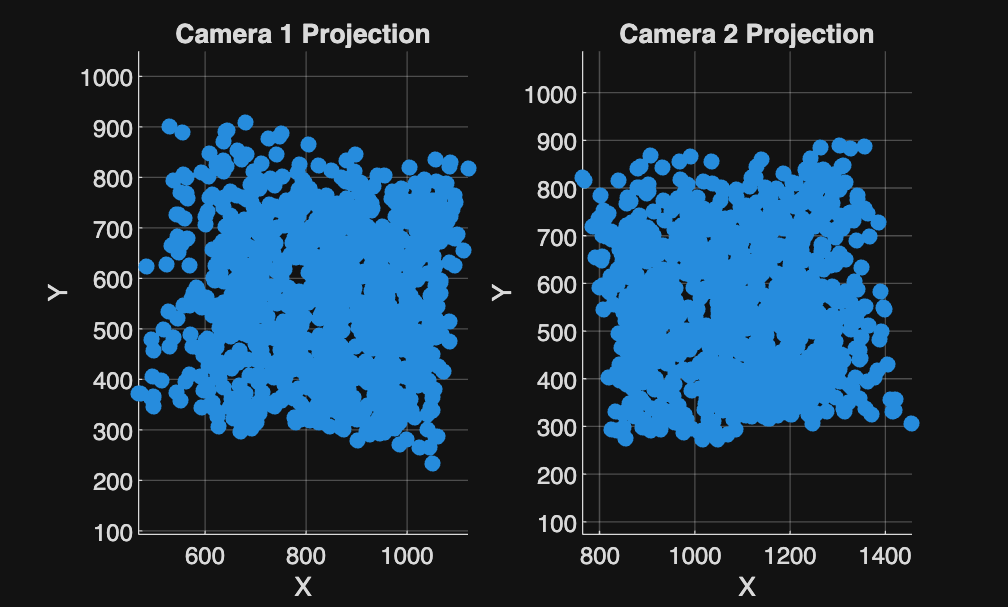

% Camera intrinsic matrix (assuming a simple pinhole model)
focal_length = 1000; % Arbitrary focal length
imageSize = [1920, 1080]; % Image resolution (width x height)

K = [focal_length, 0, imageSize(1)/2;
     0, focal_length, imageSize(2)/2;
     0, 0, 1];

% Extract parameters
focalLength = [K(1,1), K(2,2)]; % [fx, fy]
principalPoint = [K(1,3), K(2,3)]; % [cx, cy]

% Create the cameraIntrinsics object
intrinsics = cameraIntrinsics(focalLength, principalPoint, imageSize);   %#ok

synth_K = K;

% real_K = sony_camera_parameters.CameraParameters2.Intrinsics.K
 
% Compute swarm center
swarm_center = mean(points3D(:,1:3), 1);

% Define two camera positions (extrinsics)
camera_distance = 20; % Distance from swarm center
camera_height = 3; % Camera Z height
camera_separation = 5; % Separation between cameras

% Compute camera positions along x-axis (assuming cameras are aligned along x-axis)
cam1_position = [swarm_center(1), swarm_center(2), 0] + [-camera_separation/2, -camera_distance, camera_height];
cam2_position = [swarm_center(1), swarm_center(2), 0] + [camera_separation/2, -camera_distance, camera_height];

% Compute rotations to face the swarm center
cam1_direction = swarm_center - cam1_position;
cam2_direction = swarm_center - cam2_position;

R1 = eye(3); % Placeholder rotation
R2 = eye(3); % Placeholder rotation

R1(:,3) = cam1_direction / norm(cam1_direction); % Forward vector
R2(:,3) = cam2_direction / norm(cam2_direction);
R1(:,1) = cross([0 0 1]', R1(:,3)); % Right vector
R2(:,1) = cross([0 0 1]', R2(:,3));
R1(:,2) = cross(R1(:,3), R1(:,1)); % Up vector
R2(:,2) = cross(R2(:,3), R2(:,1));

T1 = -R1 * cam1_position';
T2 = -R2 * cam2_position';

% Projection matrices
P1 = K * [R1, T1];
P2 = K * [R2, T2];

% TODO: Figure out a better way to project onto optical sensors that better
% represents how cameras actually work

% Project points onto both camera planes
points3D_hom = [points3D(:,1:3), ones(numPoints,1)];
proj1_hom = (P1 * points3D_hom')';
proj2_hom = (P2 * points3D_hom')';

% Converts Homogeneous Coordinates to 2D Pixel Coordinates
proj1 = [proj1_hom(:, 1:2) ./ proj1_hom(:, 3), points3D(:,4)];
proj2 = [proj2_hom(:, 1:2) ./ proj2_hom(:, 3), points3D(:,4)];

% Add noise to proj2

% Plot projections
figure;
subplot(1,2,1);
scatter(proj1(:,1), proj1(:,2), 'filled');
title('Camera 1 Projection');
xlabel('X'); ylabel('Y'); axis equal; grid on;

subplot(1,2,2);
scatter(proj2(:,1), proj2(:,2), 'filled');
title('Camera 2 Projection');
xlabel('X'); ylabel('Y'); axis equal; grid on;

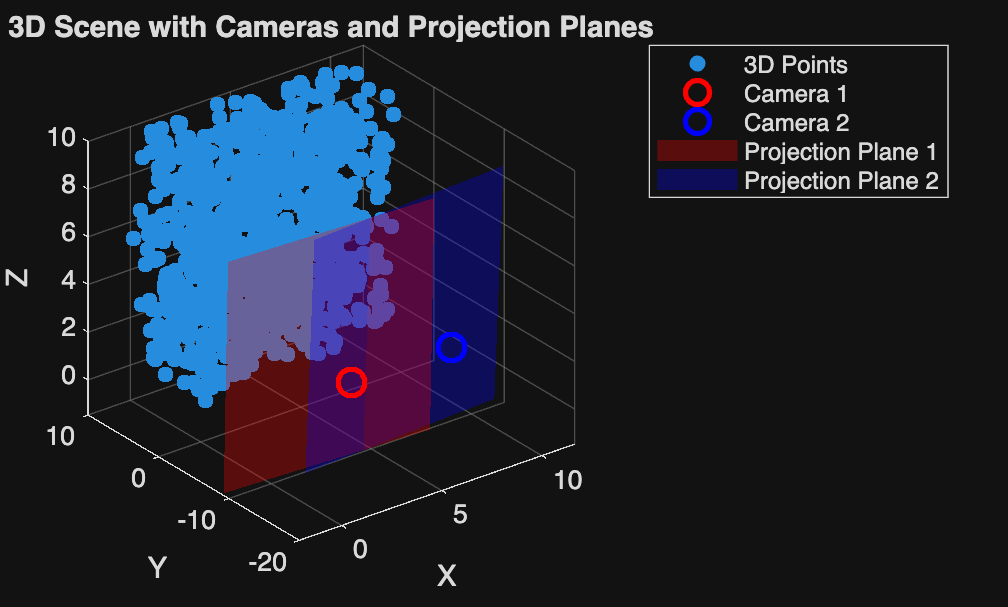

figure;
scatter3(points3D(:,1), points3D(:,2), points3D(:,3), 'filled');
hold on;
plot3(cam1_position(1), cam1_position(2), cam1_position(3), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
plot3(cam2_position(1), cam2_position(2), cam2_position(3), 'bo', 'MarkerSize', 10, 'LineWidth', 2);

% Define a projection plane in camera coordinate frame
[x_plane, y_plane] = meshgrid(linspace(-5, 5, 10), linspace(-5, 5, 10));
z_plane = ones(size(x_plane)) * 5;

% Transform projection planes into world coordinates
plane1_world = R1 * [x_plane(:)'; y_plane(:)'; z_plane(:)'] + cam1_position';
plane2_world = R2 * [x_plane(:)'; y_plane(:)'; z_plane(:)'] + cam2_position';

% Reshape for plotting
plane1_world = reshape(plane1_world', [10, 10, 3]);
plane2_world = reshape(plane2_world', [10, 10, 3]);

surf(plane1_world(:,:,1), plane1_world(:,:,2), plane1_world(:,:,3), 'FaceColor', 'red', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
surf(plane2_world(:,:,1), plane2_world(:,:,2), plane2_world(:,:,3), 'FaceColor', 'blue', 'FaceAlpha', 0.3, 'EdgeColor', 'none');

legend('3D Points', 'Camera 1', 'Camera 2', 'Projection Plane 1', 'Projection Plane 2');
xlabel('X'); ylabel('Y'); zlabel('Z');
grid on;
title('3D Scene with Cameras and Projection Planes');
hold off;

% Compute translation cross-product matrix
T_cross = [0, -T2(3), T2(2);
           T2(3), 0, -T2(1);
          -T2(2), T2(1), 0];

% Fundamental matrix: F = K^{-T} * T_cross * R * K^{-1}
F = inv(K)' * T_cross * R2 * inv(K);

% Calculate R, t, and E analytically 
[R, t, E] = computeAnalyticalRTandE(R1, R2, cam1_position, cam2_position);

% Validate epipolar constraint: cam2^T * F * cam1 = 0
proj1_h = [proj1(:,1:2), ones(numPoints,1)]';
proj2_h = [proj2(:,1:2), ones(numPoints,1)]';
errors = diag(proj2_h' * F * proj1_h);
mean_error = mean(abs(errors));
fprintf("Mean error of epipolar constraint in camera pixels is: %6.3f", mean_error)

Mean error of epipolar constraint in camera pixels is:  5.662

% Test accuracy of lab's F matrix estimation w/ synthetic data

addpath(genpath("/Users/nbonnie/Desktop/3D_reconstruction_sandbox/calfree_scripts"))
addpath(genpath("/Users/nbonnie/Desktop/3D_reconstruction_sandbox/new_scripts"))
addpath(genpath("/Users/nbonnie/Desktop/3D_reconstruction_sandbox/validation"))

calTraj.j1 = proj1;
calTraj.j2 = proj2;

% renormalize to get third coordinate equal to 1 (see Matlab doc)
points1 = calTraj.j1(:,1:2)./calTraj.j1(:,3);
points2 = calTraj.j2(:,1:2)./calTraj.j2(:,3);

% calculate fundamental matrix
F_estimation  = estimateFundamentalMatrix(points1, points2, 'Method', 'Norm8Point');

errors_exp = diag(proj2_h' * F_estimation * proj1_h);
mean_error_exp = mean(abs(errors_exp));
fprintf("Mean error of epipolar constraint in camera pixels is: %6.3f", mean_error_exp)

Mean error of epipolar constraint in camera pixels is: 675.919

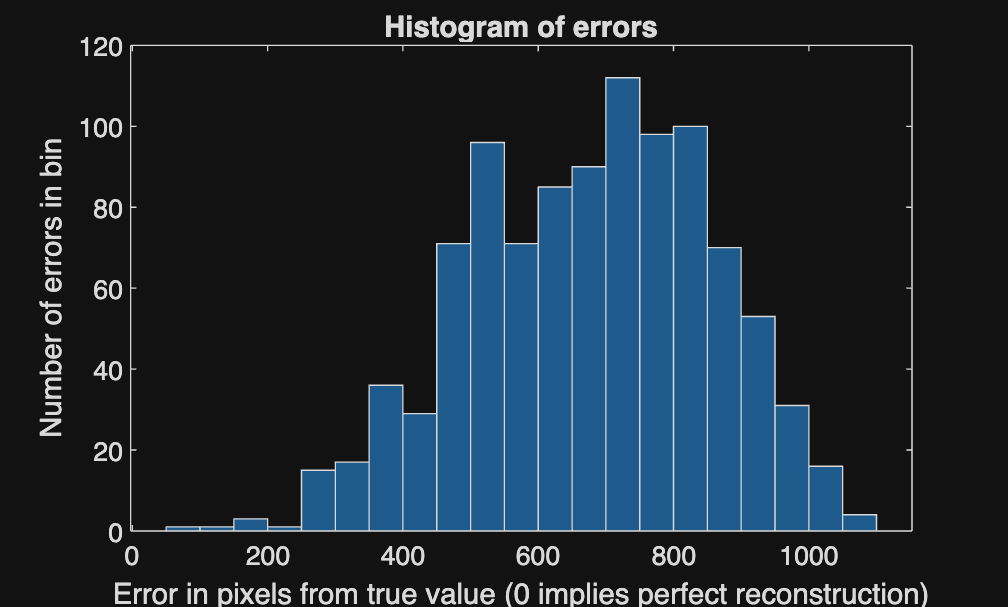

figure;
histogram(abs(errors_exp))
ylabel("Number of errors in bin")
xlabel("Error in pixels from true value (0 implies perfect reconstruction)")
title("Histogram of errors")

% LAB CODE W/ REAL ANALYTICAL VALUES -- Best case scenarie 
% (perfect estimation of parameters within hardware limitations)
stereoParamsReal.t = t;
stereoParamsReal.R = R;
stereoParamsReal.F = F;


[matched_points_1,matched_points_2] = matchStereo(proj1, proj2, stereoParamsReal, 0, 10000);

% Triangulate
P1 = K * [eye(3), zeros(3,1)];
P2 = K * [stereoParamsReal.R, stereoParamsReal.t];
xyz_best = triangulate(matched_points_1(:,1:2), matched_points_2(:,1:2), P1', P2');
xyzt_best = [xyz_best, matched_points_1(:,3)];

% Switch from camera coordinates (-x,z,y) to real coordinates (x,y,z)
xyzt_best(:,1) = -xyzt_best(:,1);
xyzt_best(:, [2, 3]) = xyzt_best(:, [3, 2]);

% Shift recon data to share a corner at (0,0,0)
xyzt_best_norm = xyzt_2_origin(xyzt_best);

% Compute match-point error at each time step
errors = compare3D(xyzt_best_norm, points3D);
fprintf('Mean Error: %.4f\n', mean(errors(:)));

Mean Error: 1.2163


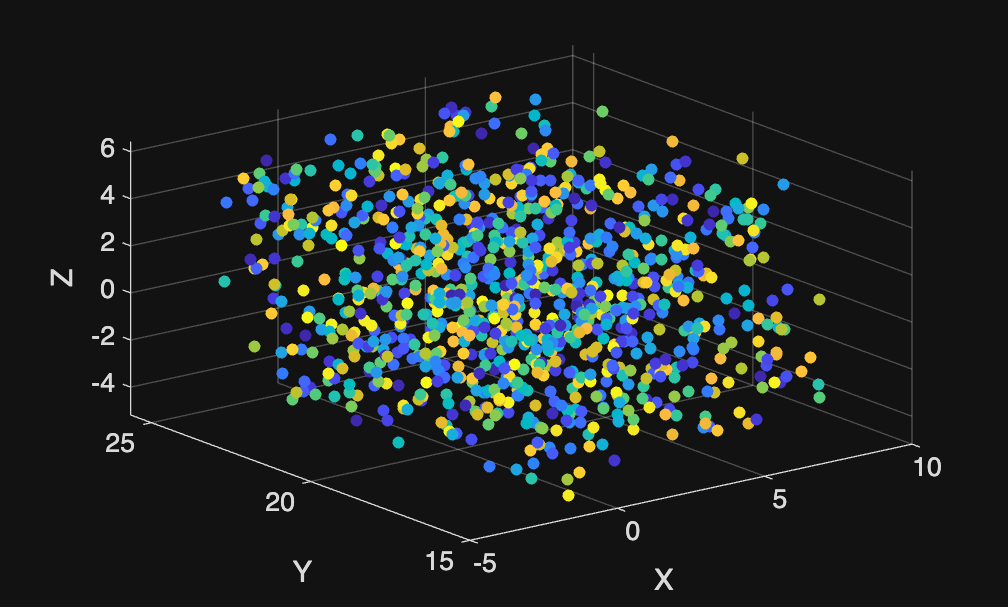


figure;
scatter3( xyzt_best(:,1) , xyzt_best(:,2) , xyzt_best(:,3), 20, xyzt_best(:,4), 'filled')
xlabel('X'); ylabel('Y'); zlabel('Z');

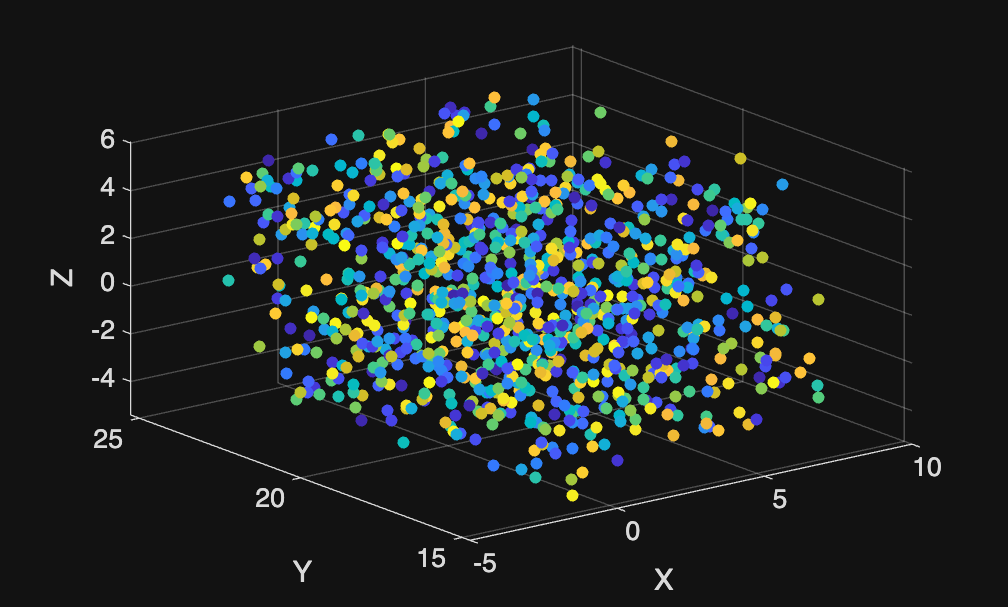

% LAB CODE W/ NEW ESTIMATED VALUES
intrinsics = K_2_cameraIntrinsics(K, 1920, 1080);
[R2, t2]= estimate_R_with_t_constraint(proj1(:,1:2), proj2(:,1:2), intrinsics);
distance_between_camera_meters = 5;

% Scale traslation matrix to use real world units
t2 = t2 ./ (1/distance_between_camera_meters);

stereoParamsNew.t = -t2;
stereoParamsNew.R = R2;
stereoParamsNew.F = F_estimation;


[matched_points_1,matched_points_2] = matchStereo(proj1, proj2, stereoParamsNew, 0, 10000); % dk is 0 here

if size(matched_points_1) < numPoints
    disp(size(matched_points_1))
    disp(size(matched_points_2))
end

% Triangulate
% Load in sony camera intrinsic parameters
% load('sony_camera_parameters.mat')
P1 = K * [eye(3), zeros(3,1)];
P2 = K * [stereoParamsNew.R, stereoParamsNew.t];
xyz = triangulate(matched_points_1(:,1:2), matched_points_2(:,1:2), P1', P2');
xyzt = [xyz, matched_points_1(:,3)];

% Flip back from camera coordinates (-x,z,y) to real coordinates (x,y,z)
xyzt(:,1) = -xyzt(:,1);
xyzt(:, [2, 3]) = xyzt(:, [3, 2]);

figure;
scatter3( xyzt(:,1) , xyzt(:,2) , xyzt(:,3), 20, xyzt(:,4), 'filled')
xlabel('X'); ylabel('Y'); zlabel('Z');

% Validate by calculating distances between recon points and original
% points

addpath(genpath("/Users/nbonnie/Desktop/3D_reconstruction_sandbox/validation"))

% Shift recon data to share a corner at (0,0,0)
xyzt_norm = xyzt_2_origin(xyzt);

% Compute match-point error at each time step
errors = compare3D(xyzt_norm, xyzt_best_norm);

% Display error statistics
fprintf('Mean Error: %.4f\n', mean(errors(:)));

Mean Error: 0.1537


fprintf('Max Error: %.4f\n', max(errors(:)));

Max Error: 0.2450


fprintf('Min Error: %.4f\n', min(errors(:)));

Min Error: 0.0321


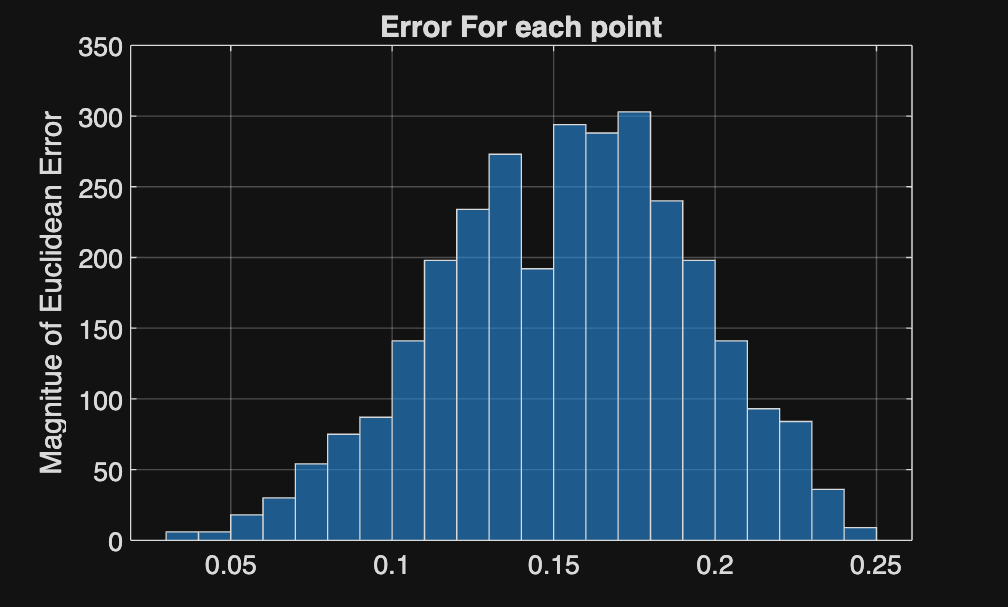

% Histogram of error for each matched pair 
figure;
histogram(errors)
ylabel('Magnitue of Euclidean Error');
title('Error For each point');
grid on;

tr = F2tR(F_estimation);
stereoParamsOld.F = F_estimation;
stereoParamsOld.t = tr.t;
stereoParamsOld.R = tr.R;

[matched_points_1,matched_points_2]=matchStereo(proj1, proj2, stereoParamsOld, 0, 10000);
%intrinsics = K_2_cameraIntrinsics(K, 1920, 1080);
tr = F2tR(F_estimation);

% Convert K to post-multiply format (needed for camera parameters object)
intrinsicMatrix1 = [K(1,1), 0, 0;
                    0, K(2,2), 0;
                    K(1,3), K(2,3), 1];

intrinsicMatrix2 = [K(1,1), 0, 0;
                    0, K(2,2), 0;
                    K(1,3), K(2,3), 1];

% Create correct stereoParams object for synth cameras
cameraParams1 = cameraParameters('IntrinsicMatrix', intrinsicMatrix1, ...
                                  'ImageSize', [1920, 1080], ...
                                  'RadialDistortion', [0,0], ...
                                  'TangentialDistortion', [0,0]);

cameraParams2 = cameraParameters('IntrinsicMatrix', intrinsicMatrix2, ...
                                  'ImageSize', [1920, 1080], ...
                                  'RadialDistortion', [0,0], ...
                                  'TangentialDistortion', [0,0]);

new_stereoParams = stereoParameters(cameraParams1, cameraParams2, tr.R, tr.t);
new_stereoParams = toStruct(new_stereoParams);
new_stereoParams.FundamentalMatrix = F_estimation;
new_stereoParams = stereoParameters(new_stereoParams);


% Triangulate
xyz = triangulate(matched_points_1(:,1:2), matched_points_2(:,1:2), new_stereoParams);
xyzt_old = [xyz, matched_points_1(:,3)];

% Switch from camera coordinates (-x,z,y) to real coordinates (x,y,z)
xyzt_old(:,1) = -xyzt_old(:,1);
xyzt_old(:, [2, 3]) = xyzt_old(:, [3, 2]);

% Shift recon data to share a corner at (0,0,0)
xyzt_old_norm = xyzt_2_origin(xyzt_old);

% Compute match-point error at each time step
errors = compare3D(xyzt_old_norm, xyzt_best_norm);
fprintf('Mean Error: %.4f\n', mean(errors(:)));

Mean Error: 8.2550


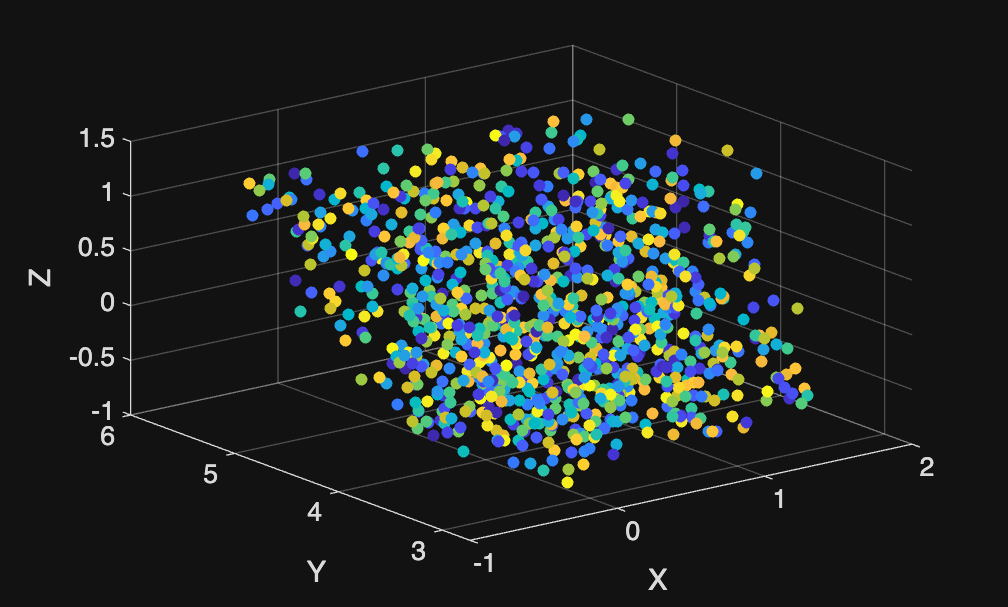


figure;
scatter3( xyzt_old(:,1) , xyzt_old(:,2) , xyzt_old(:,3), 20, xyzt_old(:,4), 'filled')
xlabel('X'); ylabel('Y'); zlabel('Z');